# Problem 2

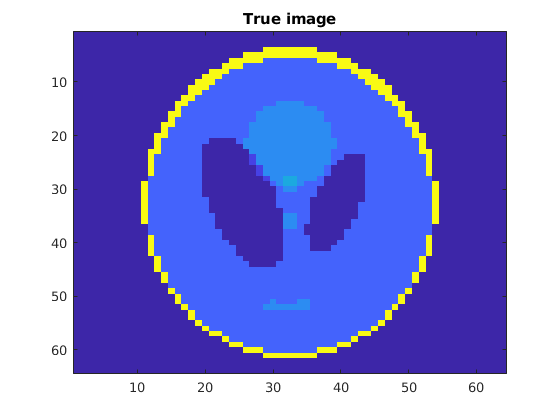

clc;
clear;
close all;
rng('default');

N = 64;          % Image is N-by-N pixels
theta = 0:2:178; % projection angles
p = 90;          % Number of rays for each angle

% Assemble the X-ray tomography matrix, the true data, and true image
[K, d, m_true] = paralleltomo(N, theta, p);

figure; imagesc(reshape(m_true, N, N));
title('True image');

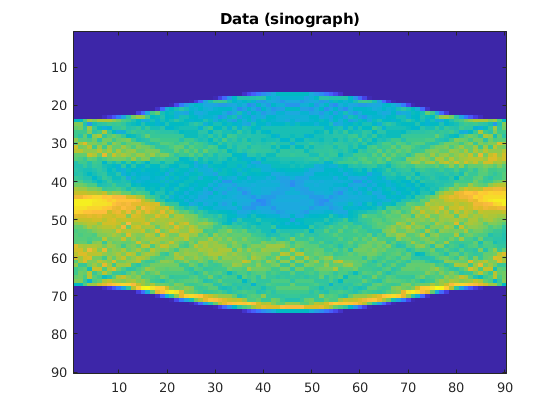

figure; imagesc(reshape(d, p, length(theta)));
title('Data (sinograph)');

% Remove possibly 0 rows from K and d (get index as well)
[K, d, idx] = purge_rows(K, d);

## A) Reconstruct m using ART. Report convergence history (i.e. residual and error norms at each iteration)

% precompute the norm of each row
K_norms = full(sum(K.^2,2));

% run ART (See ART.cpp file, compile with 'mex ART.cpp')
tic;
m_art = ART(K',K_norms,d);
toc;

Elapsed time is 11.813133 seconds.


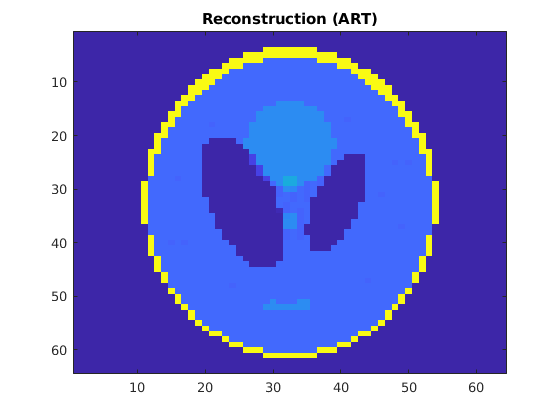

% calculate residual and error
residual_art = sqrt(sum((repmat(d,1,1000) - K*m_art).^2,1));
error_art = sqrt(sum((repmat(m_true,1,1000) - m_art).^2,1));

% plot stuff
figure; imagesc(reshape(m_art(:,1000),64,64)); title('Reconstruction (ART)');

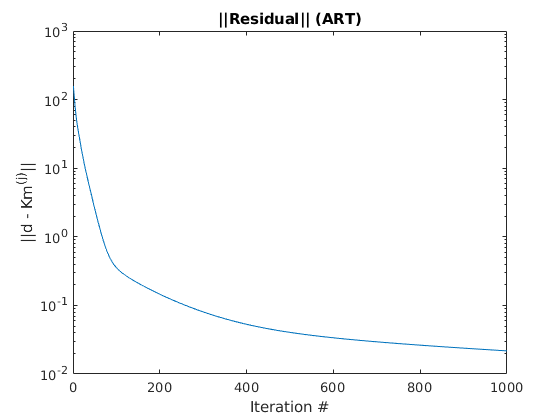

figure; semilogy(1:1000,residual_art); title('||Residual|| (ART)');
xlabel('Iteration #'); ylabel('||d - Km^{(j)}||');

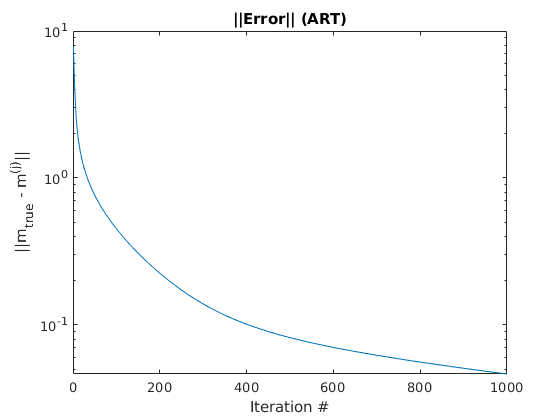

figure; semilogy(1:1000,error_art); title('||Error|| (ART)');
xlabel('Iteration #'); ylabel('||m_{true} - m^{(j)}||');

## B) Reconstruct m using SART. Report convergence history and compare with ART

SART seems to converge much slower in error/residual than ART.

% run SART (See SART.cpp file, compile with 'mex SART.cpp')
tic;
m_sart = SART(K',K_norms,d,idx);
toc;

Elapsed time is 12.299516 seconds.


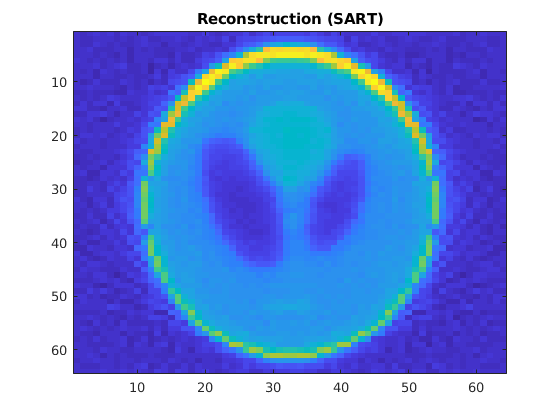

% calculate residual and error
residual_sart = sqrt(sum((repmat(d,1,1000) - K*m_sart).^2,1));
error_sart = sqrt(sum((repmat(m_true,1,1000) - m_sart).^2,1));

% plot stuff
figure; imagesc(reshape(m_sart(:,1000),64,64)); title('Reconstruction (SART)');

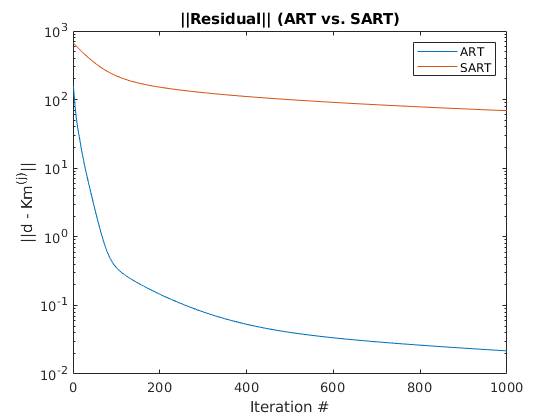

figure;
semilogy(1:1000,residual_art); hold on;
semilogy(1:1000,residual_sart);
xlabel('Iteration #'); ylabel('||d - Km^{(j)}||');
title('||Residual|| (ART vs. SART)');
legend('ART','SART');
hold off;

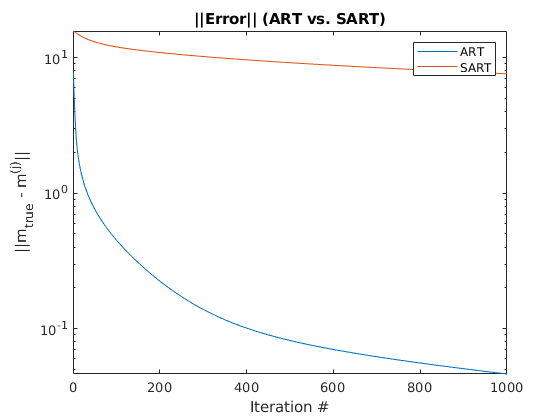

figure;
semilogy(1:1000,error_art); hold on;
semilogy(1:1000,error_sart);
xlabel('Iteration #'); ylabel('||m_{true} - m^{(j)}||');
title('||Error|| (ART vs. SART)');
legend('ART','SART');
hold off;

## C) Reconstruct m using SIRT. Report convergence history and compare with ART and SART

Both SIRT and SART are relatively comparable in results. Both converge much slower than ART.

% run SIRT (See SIRT.cpp file, compile with 'mex SIRT.cpp')
tic;
m_sirt = SIRT(K',K_norms,d);
toc;

Elapsed time is 11.662774 seconds.


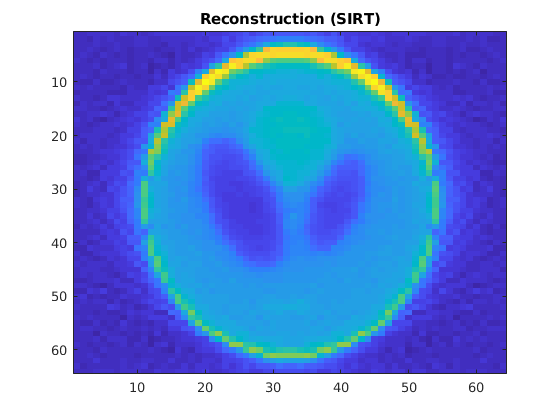

% calculate residual and error
residual_sirt = sqrt(sum((repmat(d,1,1000) - K*m_sirt).^2,1));
error_sirt = sqrt(sum((repmat(m_true,1,1000) - m_sirt).^2,1));

% plot stuff
figure; imagesc(reshape(m_sirt(:,1000),64,64)); title('Reconstruction (SIRT)');

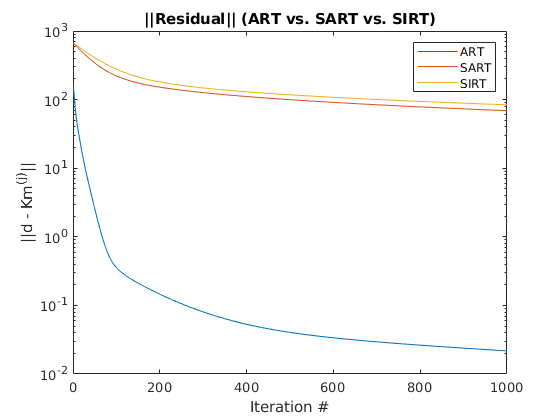

figure;
semilogy(1:1000,residual_art); hold on;
semilogy(1:1000,residual_sart);
semilogy(1:1000,residual_sirt);
xlabel('Iteration #'); ylabel('||d - Km^{(j)}||');
title('||Residual|| (ART vs. SART vs. SIRT)');
legend('ART','SART','SIRT');
hold off;

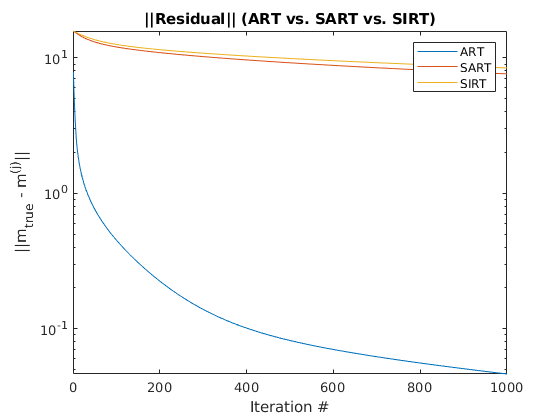

figure;
semilogy(1:1000,error_art); hold on;
semilogy(1:1000,error_sart);
semilogy(1:1000,error_sirt);
xlabel('Iteration #'); ylabel('||m_{true} - m^{(j)}||');
title('||Residual|| (ART vs. SART vs. SIRT)');
legend('ART','SART','SIRT');
hold off;

## D) Consider the case with noisy data. Reconstruct m using ART, SART, SIRT. Report convergence history and discuss what you observed.

With the addition of noise, ART does not seem to converge to the lowest error with increasing iteration. Error for ART seems to increase after a certain number of iterations, while SART and SIRT seem to continue to decrease in error with increasing number of iteations. For ART to be effective, it seems a stopping criterion would be needed to obtain an optimal solution. While ART still has lower error than both SART and SIRT in the plot, given more iterations, SART and SIRT seem like they will eventually win out in terms of error. SART seems to have better performance (converges to optimal solution in terms of error/residual) when compared to SIRT.

% create noisy data
noise_level = 0.01; % noise level.
noise_std = noise_level*norm(d,'inf');
dn = d + noise_std*randn(size(d));

% Run ART, SART, and SIRT
tic;
mn_art = ART(K',K_norms,dn);
mn_sart = SART(K',K_norms,dn,idx);
mn_sirt = SIRT(K',K_norms,dn);
toc;

Elapsed time is 33.980079 seconds.


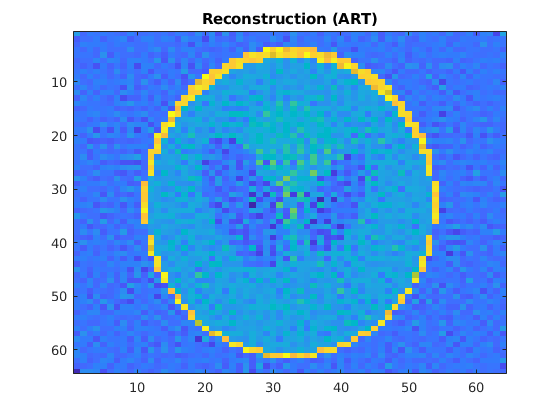

% calculate residuals and errors
residualn_art = sqrt(sum((repmat(dn,1,1000) - K*mn_art).^2,1));
errorn_art = sqrt(sum((repmat(m_true,1,1000) - mn_art).^2,1));
residualn_sart = sqrt(sum((repmat(dn,1,1000) - K*mn_sart).^2,1));
errorn_sart = sqrt(sum((repmat(m_true,1,1000) - mn_sart).^2,1));
residualn_sirt = sqrt(sum((repmat(dn,1,1000) - K*mn_sirt).^2,1));
errorn_sirt = sqrt(sum((repmat(m_true,1,1000) - mn_sirt).^2,1));

% plot stuff
figure; imagesc(reshape(mn_art(:,1000),64,64)); title('Reconstruction (ART)');

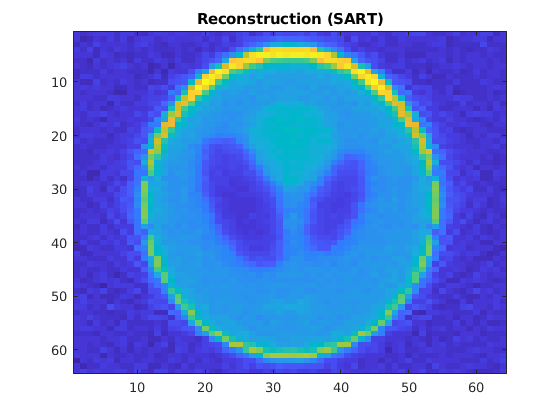

figure; imagesc(reshape(mn_sart(:,1000),64,64)); title('Reconstruction (SART)');

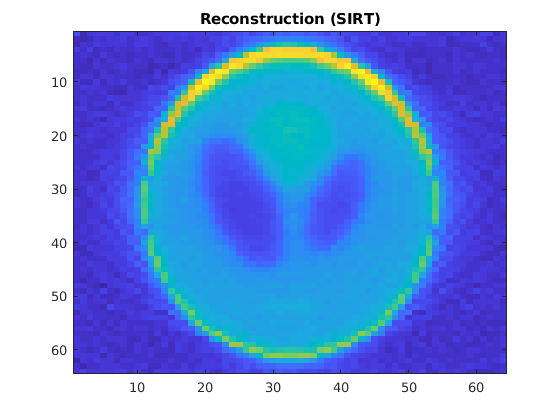

figure; imagesc(reshape(mn_sirt(:,1000),64,64)); title('Reconstruction (SIRT)');

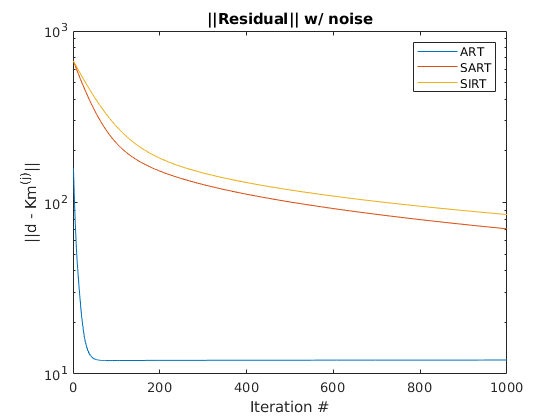

figure;
semilogy(1:1000,residualn_art); hold on;
semilogy(1:1000,residualn_sart);
semilogy(1:1000,residualn_sirt);
xlabel('Iteration #'); ylabel('||d - Km^{(j)}||');
title('||Residual|| w/ noise');
legend('ART','SART','SIRT');
hold off;

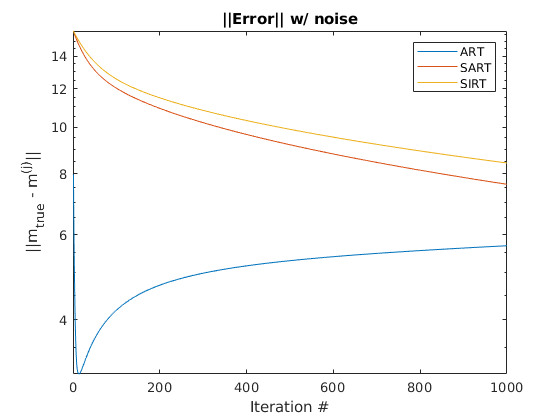

figure;
semilogy(1:1000,errorn_art); hold on;
semilogy(1:1000,errorn_sart);
semilogy(1:1000,errorn_sirt);
xlabel('Iteration #'); ylabel('||m_{true} - m^{(j)}||');
title('||Error|| w/ noise');
legend('ART','SART','SIRT');
hold off;

## E) Implement Morozov discrepancy principle as stopping criterion for ART

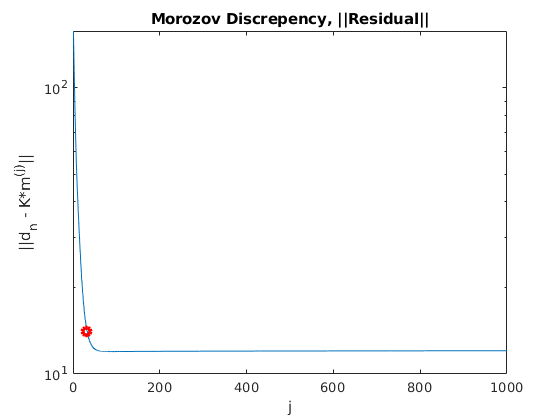

% get norm of noise data
delta = norm(noise_std*randn(size(d)));

% find morozov iteration through bisection method
a = 1000;
b = 1;
resid_a = residualn_art(a);
resid_b = residualn_art(b);
iterations = 20;
for i=1:iterations
    % find midpoint
    midpoint = round((a + b)/2);
    
    % get residual at midpoint
    resid_mid = residualn_art(midpoint);
    
    % check current intervals and assign new intervals
    if resid_a <= delta && delta <= resid_mid
       b = midpoint;
        resid_b = residualn_art(b);
    elseif resid_mid <= delta && delta <= resid_b
        a = midpoint;
        resid_a = residualn_art(a);
    else
        error(['Optimal j outside bounds! \' ...
            'Increase initial j search range.'])
    end
end
% get optimal morozov j and resid
j_opt = round((a + b)/2);
resid_opt = residualn_art(j_opt);

% plot morozov discrepency
figure;
semilogy(1:1000,residualn_art); hold on;
semilogy(j_opt, resid_opt, 'ro', 'Linewidth', 3);
title('Morozov Discrepency, ||Residual||');
xlabel('j'); ylabel('||d_{n} - K*m^{(j)}||');
hold off;

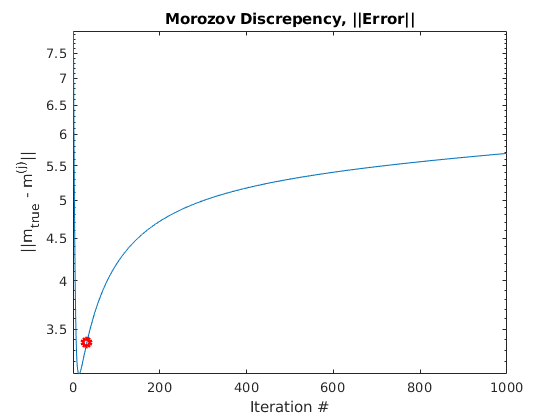

figure;
semilogy(1:1000,errorn_art); hold on;
semilogy(j_opt,errorn_art(j_opt), 'ro', 'Linewidth', 3);
title('Morozov Discrepency, ||Error||');
xlabel('Iteration #'); ylabel('||m_{true} - m^{(j)}||');
hold off;

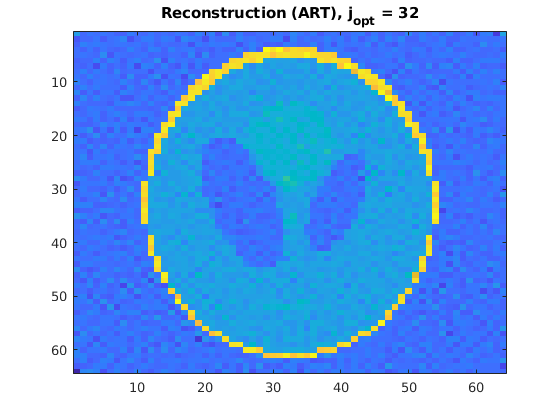

% plot image
figure; imagesc(reshape(mn_art(:,j_opt),64,64)); title(['Reconstruction (ART), j_{opt} = ' num2str(j_opt)]);